# Zebrafish group mapping monte carlo

version 3 

JP -   May  2024

Set value of *avgfracmap* to the measured value of the cross-day accuracy (see protocol in paper)

Set value of *stdfracmap* to the measured std of *avgfracmap*

Set value of *avgoffdiag* to the measured value of inaccurate matches to a single class when measuring cross-day accuracy

Set value of *stdoffdiag* to the measured std of *avgoffdiag*

Additional parameters for simulation

nsims  %number of simulated experiments 

NG %number of independent  classes

NFmax  %maximum number of fish images in a day per group (assume  same for all days and fish)

NFchoice  %Suggest choice for typical dataset

Nrep  %number of times to repeat sims to gather repeat uncertainty

prange   %testing range for fractional mapping success; 

Uses the measured fractional mappings between days to simulate likelihood of achieving measured outcome

% Set experiment parameters: determined empirically for 5 classes of
% Zebrafish used in this experiment
avgfracmap = 0.8159; %fraction of images correctly mapped day between 1-day separated adject data sets 
% using all images on second day to create the correct cross-day class mapping (~100 images leads to very accurate class mapping)
avgoffdiag = 0.0460; % average fraction assigned to one of the other 4 classes
stdfracmap = 0.1511;
stdoffdiag = 0.0662;

mapstats=struct('p',avgfracmap,'np',avgoffdiag,'ps',stdfracmap,'nps',stdoffdiag);

nsims=200;  %number of simulated experiments 
NG=5;  %number of independent fish (# classes)
NFmax=20;  %maximum number of fish images in a day per group (assume  same for all days and fish)
NFchoice=5; %Suggest choice for typical dataset
Nrep=8; %number of times to repeat sims to gather repeat uncertainty
prange = [1:-0.1:0,mapstats.p];  %testing range for fractional mapping success; 

%Arrays for sim results
fullresults=struct('succ',zeros(NFmax,length(prange)),'std',zeros(NFmax,length(prange)));
NFdepend = struct('succ',zeros(1,NFmax),'std',zeros(1,NFmax));


prange = sort(prange,'descend');  % include actual measured value in range
nfi = find(prange == mapstats.p);  %index to measured value of mapping prob

for i=1:NFmax   
    disp('Processing number of images per class: '),i
    [fullresults.succ(i,:),fullresults.std(i,:)] = ZebraSim(mapstats, prange, nsims, NG, i, Nrep);
    NFdepend.succ(i) = mean(fullresults.succ(i,nfi));
    NFdepend.std(i) = mean(fullresults.std(i,nfi));
end

Processing number of images per class: 


i = 1

Processing number of images per class: 


i = 2

Processing number of images per class: 


i = 3

Processing number of images per class: 


i = 4

Processing number of images per class: 


i = 5

prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
prob=0.8
p

Processing number of images per class: 


i = 6

Processing number of images per class: 


i = 7

Processing number of images per class: 


i = 8

Processing number of images per class: 


i = 9

Processing number of images per class: 


i = 10

Processing number of images per class: 


i = 11

Processing number of images per class: 


i = 12

Processing number of images per class: 


i = 13

Processing number of images per class: 


i = 14

Processing number of images per class: 


i = 15

Processing number of images per class: 


i = 16

Processing number of images per class: 


i = 17

Processing number of images per class: 


i = 18

Processing number of images per class: 


i = 19

Processing number of images per class: 


i = 20

st = "Number of groups: 5 ; Average mapping prob 0.8159"

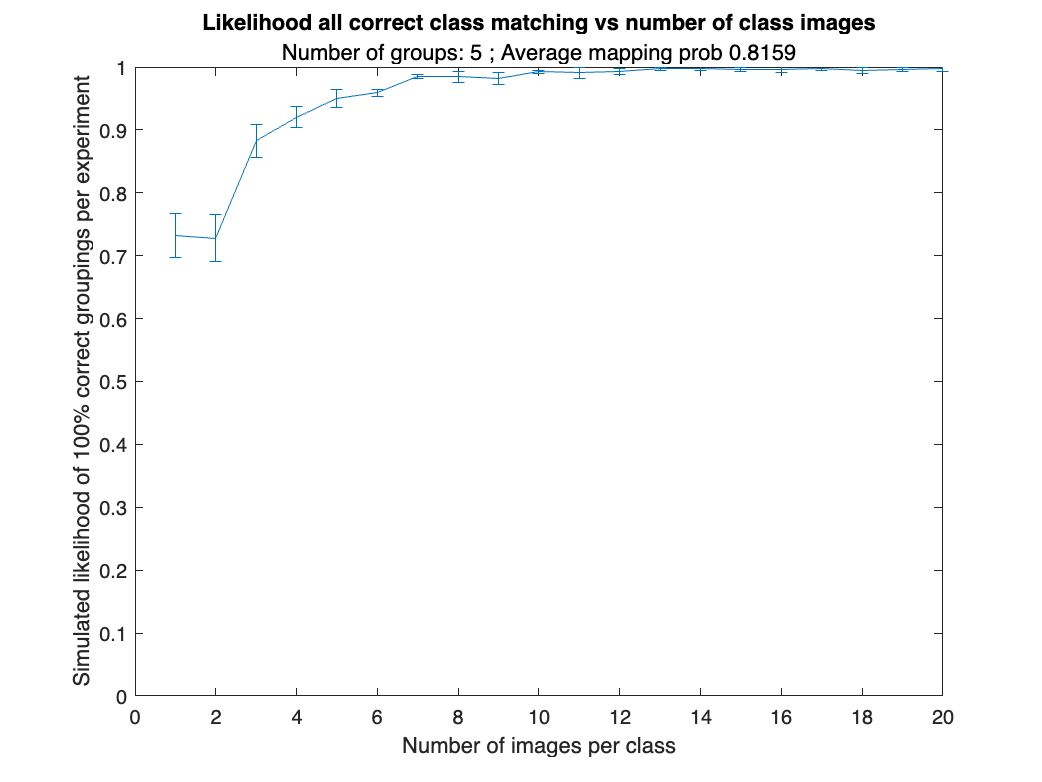


plot_NFdepend(NFdepend, mapstats, NG, NFmax);

st = "Number of groups: 5 ; Number of images per group 5"

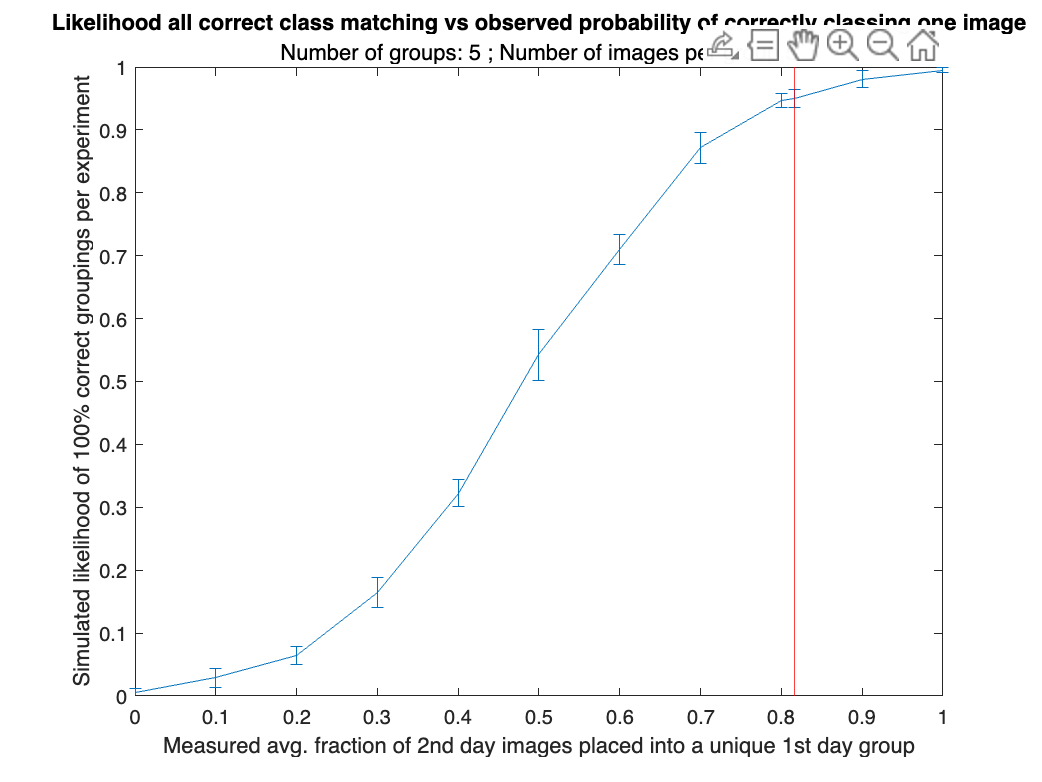


typicalres = struct('succ',fullresults.succ(NFchoice,:),'std',fullresults.std(NFchoice,:));
plot_stats(typicalres, prange, mapstats, NG, NFchoice)

function [a,b] = ZebraSim(mapstats, prange, nsims, NG, NF, Nrep)


%Storage of temp and final results
tempresults=struct('succ',zeros(Nrep,length(prange)));
results=struct('succ',zeros(1,length(prange)),'std',zeros(1,length(prange)));

%cycle through repeated sims
for l=1:Nrep
            

    %Cycle through mapping success prob prange using the measured std dev 
    
    avgsucc = zeros(1,length(prange)); %mapping successes (fraction
                                            %successful) for all grps over all
                                            %exp's for the a given measured
                                            %mapping success probability p
    stdsucc = zeros(1,length(prange)); %std on the above number    
                                           
    i=0;
    for j=prange
        i=i+1; %index for mapping probabilty 
        pmap=j;  %set mapping success for loop j
        stdpmap=mapstats.ps;  %set standard dev for loop j (constant here but could vary)
    
    %cycle through experiments
        grps = zeros(nsims,NG);  %Group mapping decision for each experiment; correct
        % mapping decision should be 1:NG
        grpsucc = zeros(1,nsims);  %counts whether an experiment has all NG groups mapped
                                %correctly (1) or not (0)
        for k=1:nsims    %experiment repeat loop
            %One experiment has NG classes, NF class images per class
            %The correct mapping of each image is assumed independent of class
            %For a single experiment repeat, fraction of images in a class
            %correctly mapped is pmap where pmap value is drawn from normal
            %distribution of width stdpmap.
    
            %For kth experiment, pmap has value drawn from normal distribution
            %of width stdpmap about mean of pmap
            pmapk = pmap + mapstats.ps*randn(1);
            pmapk = max([pmapk,0]);  %one-sided spread in pmapk value when pmap close to 1
            pmapk = min([pmapk,1]);
    
            % One experiment array NGxNF of mapping group mapped to 
            success1 = get_mapprobs(NG, NF, pmapk);
    
            %Determine class mapping of group based on most frequently occuring mapping
            %among all images for each group
            grps(k,:) = mode(success1,2);

            %Check is only one group is misclassed; if so, check is
            %misclassing overlaps with another classing with higher
            %certainty. In that case, reassign the class to the missing
            %class.
%===========================================
            missone= (grps(k,:)./(1:NG) == ones(1,NG)); %should be all ones; sum is # matched
            if (sum(~missone) == 1)
                mismatchgrp=find(~missone);
                grps(k,mismatchgrp) = mismatchgrp;  % set equal to correct group since it is 
                % only one not matched with high enough prob.
            end
% %==========================================

            %If experiment group mapping vector isn't [1,2,3,4,...,NG] then a mismatch
            %occurred.
            q=1:NG;
            grpsucc(k) = isequaln(grps(k,:),q); %1 if all grps match; 0 if one or more
                                                %mismatch
            % if NF == 4
            %     disp('stopping')
            % end
        end %experiment loop
        
        avgsucc(i) = sum(grpsucc)/nsims; 
 
    end %mapping success loop

    tempresults.succ(l,:) = avgsucc;
   
end

for i=1:length(prange)
    results.succ(i)=mean(tempresults.succ(:,i));
    results.std(i)=std(tempresults.succ(:,i));
end


%for return
a = results.succ;
b = results.std;


end





function sm = get_mapprobs(NG, NF, pmapk)

% Initialize group mappings    
    sm=zeros(NG,NF);

    %Assign successfull and unsuccessfull mappings
    for j=1:NG
        sm(j,:)=rand(1,NF) < pmapk;   % frac pmapk of time an element of rand() is <
         if (pmapk > 0.8) & (pmapk < 0.82) & NF == 5
              disp('prob=0.8')                  % pmapk since rand() is uniform
         end                              % sampling of [0,1]
        sm(j,:)=sort(sm(j,:),'descend')*j;  %put all the successful mappings first so
                                            %end can be padded as need for
                                            %unsuccessful mappings; j is
        smend=sum(sm(j,:)>0);                     %group number
        unsm=1:NG;  % define groups that are not the successfull map
        unmask=unsm ~= j;
        unsm=unsm(unmask); %has length NG-1; missing group j

        %Pad sm as needed with other grps
        % set up a random index into the other (non-primary) groups
        %Assume uniform prob for mapping to these incorrect grps
%       
        if smend ~= NF  
            %Check for need for at least 1 pad
            Q = NF - smend; % dimension of pad
            padi=randi(NG-1,1,Q);  %random index into unsm sampled unsuccessful groups
            pad = unsm(padi);
            sm(j,smend+1:end)=pad;
        end

    end
            


end



function plot_stats(results, prange, mapstats, NG, NF)

avgsucc=results.succ;
stdsucc=results.std;

Markers = {'+','*','x','v','d','^','s','>','<','o'};


errorbar(prange,avgsucc,stdsucc)
ylim([0,1]);
xlim([0,1]);

hold on
plot([mapstats.p,mapstats.p],[0,1],'r') %adds measured value for reference
%legend('','','','','','Fraction w/o all groups matched correctly','Average measured fraction','Location','southeast')
title('Likelihood all correct class matching vs observed probability of correctly classing one image')
st=strcat("Number of groups: ",string(NG)," ; Number of images per group ",string(NF))
subtitle(st)
xlabel('Measured avg. fraction of 2nd day images placed into a unique 1st day group');
% X axis is then an indicator of temporal drift where value ~1 means likely
% very similar images to day 1 and value near 1/NG means uncorrelated
% images
ylabel('Simulated likelihood of 100% correct groupings per experiment')


hold off



end



function plot_NFdepend(NFdepend, mapstats, NG, NFmax)

% Plot how % success depends on number of images NF

avgsucc=NFdepend.succ;
stdsucc=NFdepend.std;

Markers = {'+','*','x','v','d','^','s','>','<','o'};


errorbar(1:NFmax,avgsucc,stdsucc)
ylim([0,1]);
xlim([0,NFmax]);

title('Likelihood all correct class matching vs number of class images')
st=strcat("Number of groups: ",string(NG)," ; Average mapping prob ",string(mapstats.p))
subtitle(st)
xlabel('Number of images per class');
ylabel('Simulated likelihood of 100% correct groupings per experiment')


end
